# Exercise 4:

In htis task we investigate two methods of design of a feedback control system. Firstly we will utilize Matlab's Control System Designer GUI, then we will apply Ziegler-Nichols method for the same system, and finally we will compare the results, as well as ease of use of each method.

#### 1) Defining the system and time domain specifications:

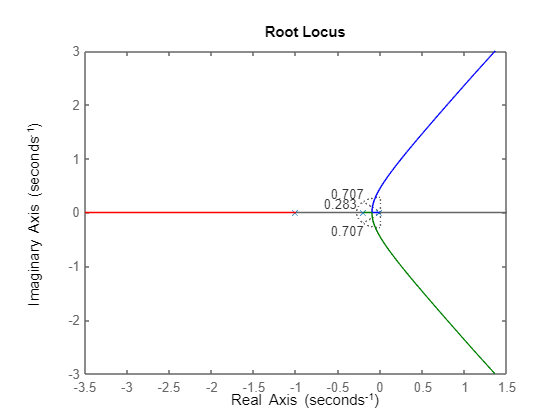

%defining the system of interest

K=8;               %gain
Z=[];              %zeros
P=[-0.01,-0.2,-1]; %poles
sys=zpk(Z,P,K);    %transfer funtion

%defining system specifications:

zeta=0.707;        %damping ratio of dominant close-loop poles
wn=0.2829;         %natural frequency of dominant close-loop poles

%plotting the rlocus plot of the system, and generating a grid of constant
%damping factors and natural frequencies

rlocus(sys)
sgrid(zeta,wn)

#### 2) The Root-Locus Design GUI (sisotool) tool of Matlab Control System Toolbox:

- Firsty we set up system specifications:

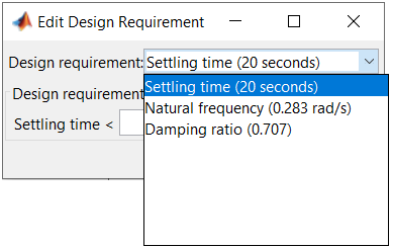

rys.1 system specifications 

- Secondly we add a zero to the system to the right of the pole with the smallest magnitude. Adding zero allows us to shift the dominant poles to the left half-plane. 

- Finally we adjust the position of the poles such that they fit within the system specifictations. As a result we obtain the following locus plot:

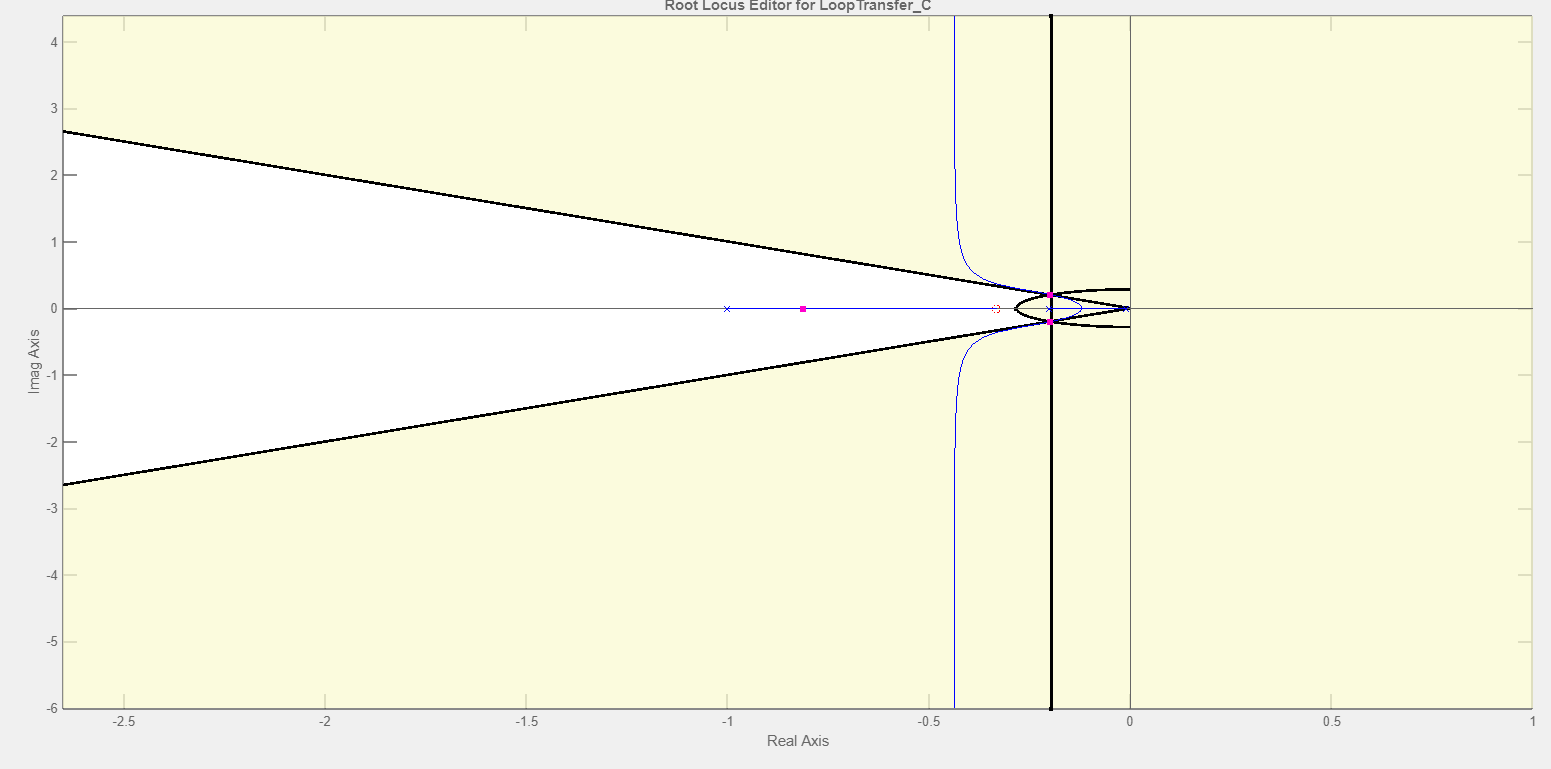

rys.2 Root locus plot with system specification limitations

Based on the compensator data:

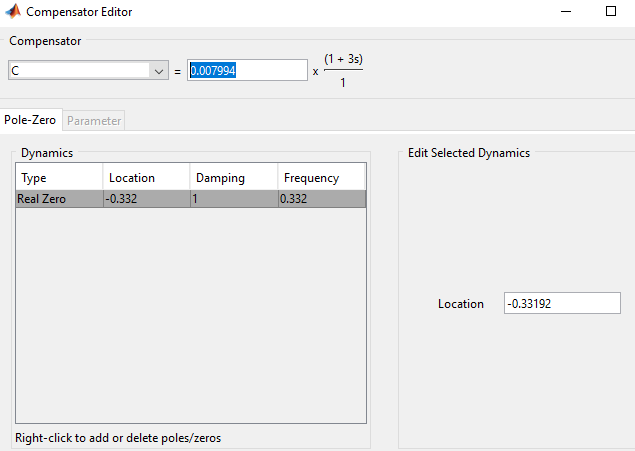

rys.3 obtained compensator values

the PD controller is approximately 0.008 + 0.024s.

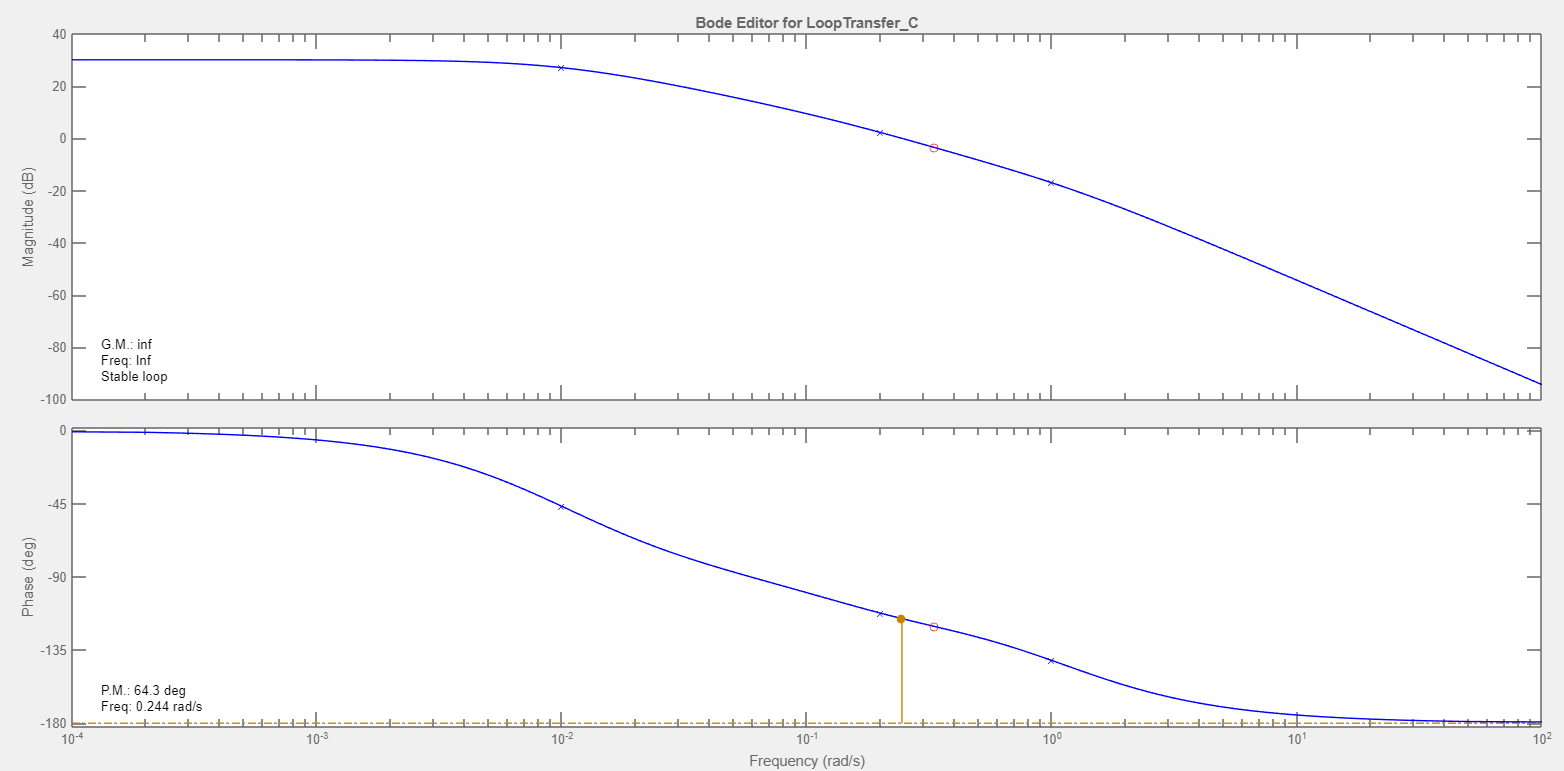

rys.4 Bode plot of the system

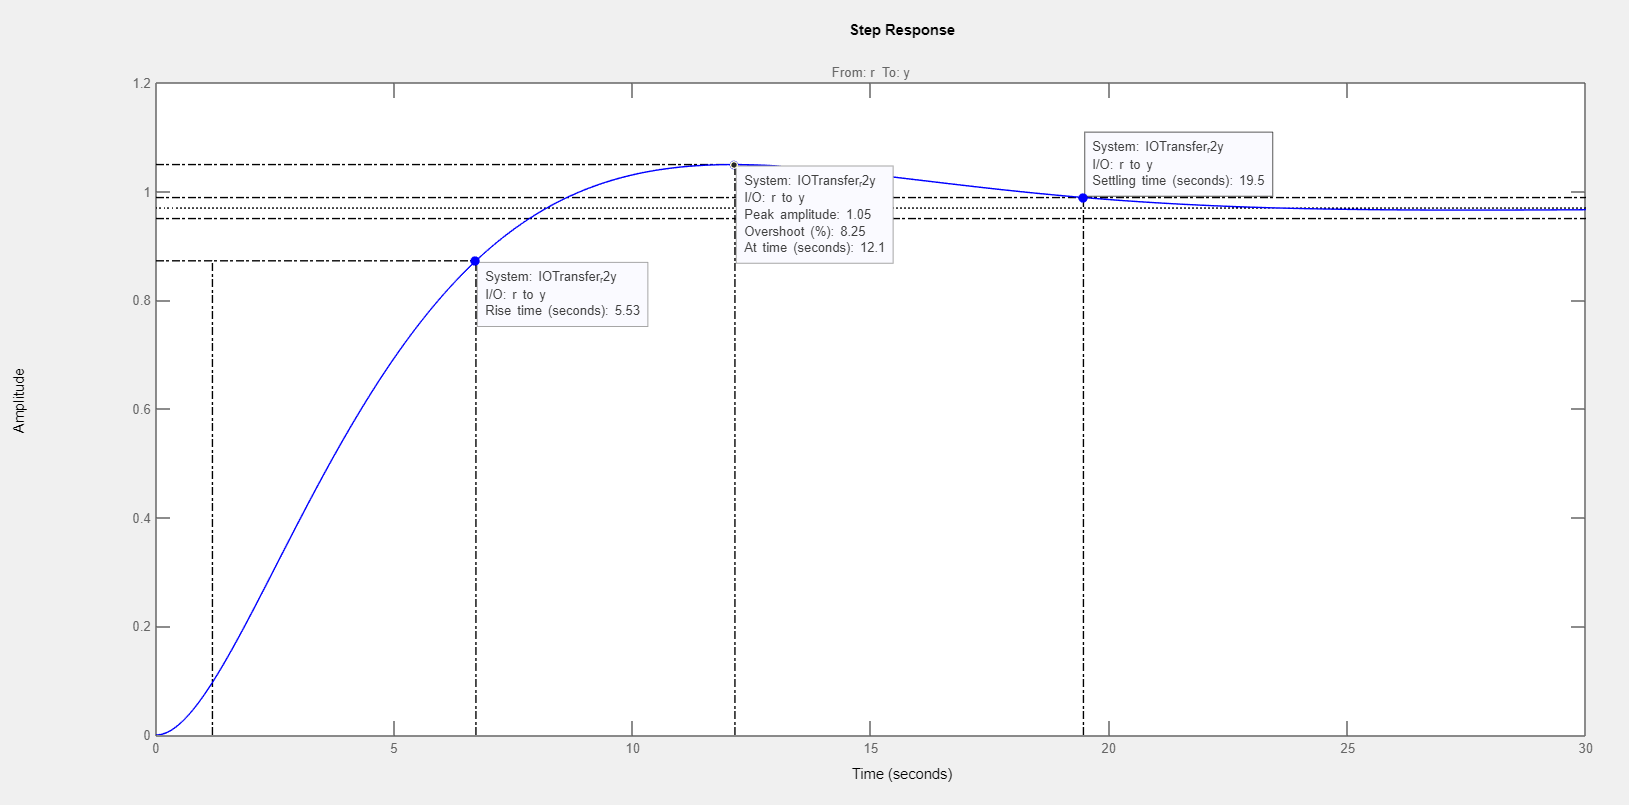

rys.5 Close-loop step response of the system

%loading finished system from Control Designer 

load('ControlSystemDesignerSession.mat')
%controlSystemDesigner('ControlSystemDesignerSession.mat')

#### 3) Ziegler-Nichols method of tuning a PID controller:

 It is performed by setting the *I* (integral) and *D* (derivative) gains to zero. The P (proportional) gain (Kp) is then increased until it reaches the ultimate gain (Ku), at which the output of the control loop has stable and consistent oscillations. Ku and the oscillation period Tu are then used to set the P, I, and D gains depending on the type of controller used and behaviour desired:

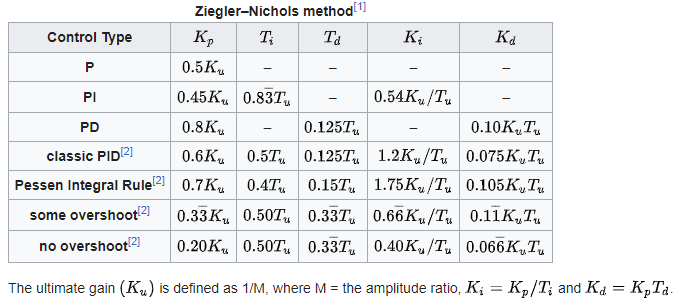

rys.6 Table for PID tunning using Ziegler-Nichols method.

- The ultimate gain Ku can be read from the rlocus plot present in the part 1) of the task. It lays on the crossing of the locus line and the imaginary axis. The value for our system is:

%From locusplot in 1)
Ku=0.0319; 

- The fastest way to find Tu is by creating a simuling model of our system, then using the cursor measurement function within the scope we can read the period Tu directly from the obtained plot.

%From simulink
% =open('Ex4sim.slx')
Tu=13.653;

- Having found Ku and Tu we can now find the remaining values needend to tune our PID. 

K1=Ku;
Ti=Tu/2;
Td=Tu/8;
Ki=K1/Ti;
Kd=K1*Td;
W=pid(K1,Ki,Kd);
H=1;

- Finally we can create the system with feedback tuned by the obtained PID, and plot its step function

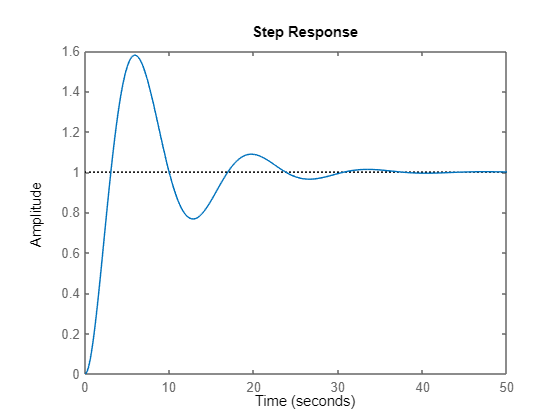

Y=feedback(sys*W,H);
step(Y)

stepinfo(Y)

ans = struct with fields:
         RiseTime: 2.0813
    TransientTime: 28.8391
     SettlingTime: 28.8391
      SettlingMin: 0.7680
      SettlingMax: 1.5796
        Overshoot: 57.9573
       Undershoot: 0
             Peak: 1.5796
         PeakTime: 5.9107


#### 4) Results:

rys.7 table containing key characteristics of each designed system.

Based on the results presented above we can conclude that the Root-Locus method is better than Ziegler-Nichols. We have obtained more accurate values with it, while having to perform less work. In general Root-Locus method will always have an advantage, because it does not require any hand calculations which due to rounding errors increase the overall error of the obtained results. Root-Locus method was more intuitive, and quicker (since we only had to adjust pre-made plots). Due to those considerations we would always prefer to use Root-Locus.